In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$q1 = \frac{R^{2}\,g^{2}\,m}{V^{2}\,c}$$

$$q2 = -\frac{2\,R\,g}{V}$$

$$q3 = -\frac{R}{L}$$

$$q4 = \frac{1}{L}$$

ro1S = 0.2707

ro1I = 0.2474

ro2S = 45.9200

ro2I = 40.4380

ro3S = 1.6000

ro3I = 1.4599

$$q1 = \frac{9212.28\,R^{2}}{V^{2}}$$

$$q2 = -\frac{19.62\,R}{V}$$

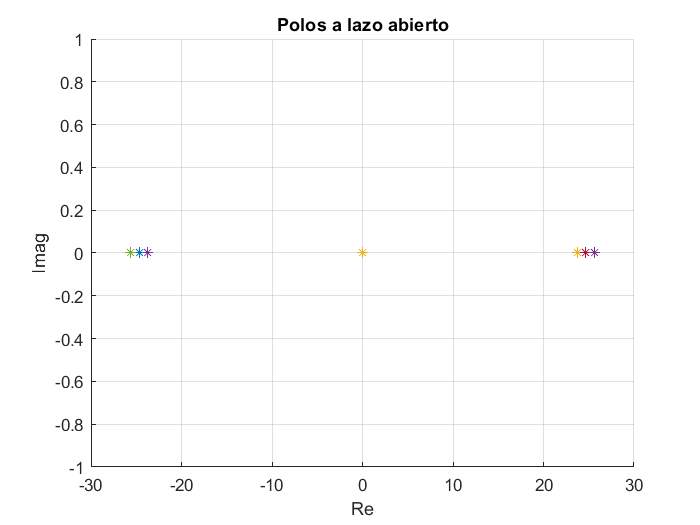

a =     0.2474    0.2574    0.2674


b =    40.4380   40.5380   40.6380   40.7380   40.8380   40.9380   41.0380   41.1380   41.2380   41.3380   41.4380   41.5380   41.6380   41.7380   41.8380   41.9380   42.0380   42.1380   42.2380   42.3380   42.4380   42.5380   42.6380   42.7380   42.8380   42.9380   43.0380   43.1380   43.2380   43.3380   43.4380   43.5380   43.6380   43.7380   43.8380   43.9380   44.0380   44.1380   44.2380   44.3380   44.4380   44.5380   44.6380   44.7380   44.8380   44.9380   45.0380   45.1380   45.2380   45.3380


c =     1.4599    1.5599


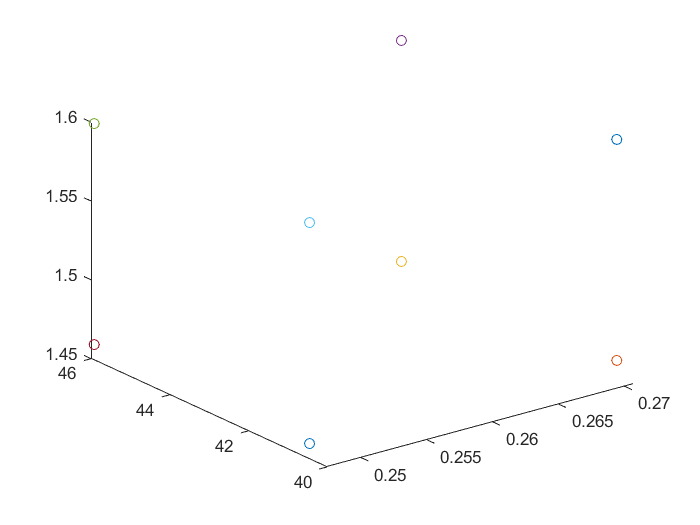

Theta = 0

A1 =          0   -1.0000         0         0
         0         0    1.0000         0
         0  563.0462         0   -4.9478
         0         0         0  -40.4380


A4 =          0   -1.0000         0         0
         0         0    1.0000         0
         0  674.1802         0   -5.4141
         0         0         0  -45.9200


B1 =          0
         0
         0
    1.6000


B2 =          0
         0
         0
    1.4599



 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.032632
     2                        0.014128
     3                        0.014128
     4                    6.844302e-03
     5                    3.180048e-03
     6                    3.180048e-03
     7                    3.730343e-04
     8                    1.355044e-04
     9                    7.503157e-05
    10                    8.229670e-06
    11                    -7.528429e-05

 Result:  best value of t: -7.528429e-05
          f-radius saturation:  0.000% of R =  1.00e+09
 


K = 	1.0e+03 *

   -5.5511    8.4846    0.3328   -0.0089


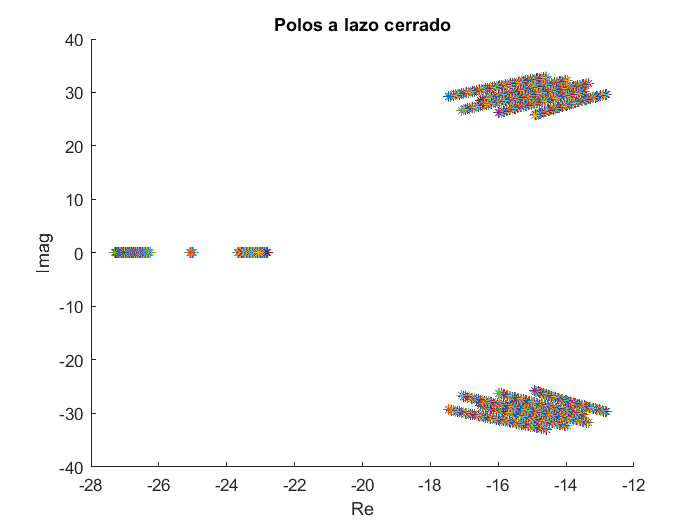

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)

% Se sustituyeron los valores netos de
% http://dx.doi.org/10.1080/00207729608929322 
% R = 27.7 Ohm , c = 1.24 * 10^-4 Nm^2 A^2, M =11.87gr=0.01187Kg, 
% se variara la tensión del punto de equilibrio de 106,02V a 111,97V y la
% resistencia entre 27.7Ohm y 28.7Ohm y la inductancia en un 10% 0.715 y 0.585, En este caso se planteo ro1=R/V y
% ro2 = R/L, estos valores varían dentro de ciertas cotas 


%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2)
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)))
%q3 A(3,3)
q3 = -R/L
%q4 B(3,1)
q4 = 1/L
% cota superior de ro1 = R/V
ro1S = 28.7/106.02 % originalmente era 29.7, pero era mucha carga para el sistema
% cota superio de ro1
ro1I = 27.70/111.97 

% cota superior de ro2 = R/L

ro2S = 28.7/0.625 % orgininalmente era 29.7, pero era mucha carga para el sistema

% cota inferior de ro2

ro2I = 27.7/0.685 % esta condicion no puede existir al mismo tiempo que ro1S o ro3s es contradictorio

% cota superior de ro3 = 1/L

ro3S = 1/0.625 % orgininalmente era 29.7, pero era mucha carga para el sistema, esta condición no puede existe al mismo tiempo que ro2I

% cota inferior de ro2

ro3I = 1/0.685

% Sustituimos los valores por defecto 


% Sustituimos los valores por defecto 

q1 = vpa(subs(q1, [c g m], [1.24e-4 9.81 0.01187]),6)

q2 = vpa(subs(q2, [c g m], [1.24e-4 9.81 0.01187]),6)

% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

%q4 pertenece a:

%Defino el sistema aumentado 

figure
for  ro1=ro1I:0.01:ro1S
    for ro2=ro2I:0.1:ro2S
        A=[0 -1 0 0;0 0 1 0;0 9.2e+3*ro1^2 0 -20*ro1;0 0 0 -ro2];
        p=eig(A);
        hold on
        plot(real(p(1)),imag(p(1)),'*')
        plot(real(p(2)),imag(p(2)),'*')
        plot(real(p(3)), imag(p(3)), '*')
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off



a=ro1I:0.01:ro1S
b=ro2I:0.1:ro2S
c=ro3I:0.1:ro3S

% Dibujamos el politopo 
figure
hold on
plot3(ro1I, ro2I, ro3I, 'o')
plot3(ro1S, ro2I, ro3I, 'o')
plot3(ro1S, ro2S, ro3I, 'o')
plot3(ro1S, ro2S, ro3S, 'o')
plot3(ro1I, ro2S, ro3S, 'o')
plot3(ro1I, ro2I, ro3S, 'o')
plot3(ro1I, ro2S, ro3I, 'o')
plot3(ro1S, ro2I, ro3S, 'o')
hold off
view(3)
% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
Theta = 0.

% Planta
% R=27.7Ohm y=0.0156m 
A1=[0 -1 0 0;0 0 1 0;0 9.2e+3*ro1I^2 0 -20*ro1I;0 0 0 -ro2I]
% R=27.7Ohm y=0.0174m
% A2=[0 -1 0 0;0 0 1 0;0 9.2e+3*ro1S^2 0 -20*ro1S;0 0 0 -ro2I]
% R=28.7Ohm y=0.0156m
% A3=[0 -1 0 0;0 0 1 0;0 9.2e+3*ro1I^2 0 -20*ro1I;0 0 0 -ro2S]
% R=28.7Ohm y=0.0174m
A4=[0 -1 0 0;0 0 1 0;0 9.2e+3*ro1S^2 0 -20*ro1S;0 0 0 -ro2S]
% 

B1=[0; 0; 0; ro3S]
B2=[0; 0; 0; ro3I]

 fileID = fopen('textfile.txt', 'a');

% Especificaciones región reubicación de polos

Alfa=1;

Ro=55;

% Creación sistema LMI
setlmis([])


% Restricciones asociadas al parámetro Alfa



% Variables LMIs
S=lmivar(1,[4 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 4]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨1S + 𝑺𝑨1𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B2,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨2S+ 𝑺𝑨2𝑻 + 𝑩1R + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([3 1 1 S],A2,1,'s');
% lmiterm([3 1 1 R],B1,1,'s');
% lmiterm([3 1 1 S],2*Alfa,1);

% 𝑨3S + 𝑺𝑨3𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([4 1 1 S],A3,1,'s');
% lmiterm([4 1 1 R],B1,1,'s');
% lmiterm([4 1 1 S],2*Alfa,1);

% 𝑨4S+ 𝑺𝑨4𝑻 + 𝑩1R + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([5 1 1 S],A4,1,'s');
lmiterm([5 1 1 R],B1,1,'s');
lmiterm([5 1 1 S],2*Alfa,1);

% 𝑨1S + 𝑺𝑨1𝑻 + 𝑩2S + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([6 1 1 S],A1,1,'s');
% lmiterm([6 1 1 R],B2,1,'s');
% lmiterm([6 1 1 S],2*Alfa,1);

% 𝑨2S+ 𝑺𝑨2𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([7 1 1 S],A2,1,'s');
% lmiterm([7 1 1 R],B2,1,'s');
% lmiterm([7 1 1 S],2*Alfa,1);

% 𝑨3S + 𝑺𝑨3𝑻 + 𝑩2S + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([8 1 1 S],A3,1,'s');
% lmiterm([8 1 1 R],B2,1,'s');
% lmiterm([8 1 1 S],2*Alfa,1);

% 𝑨4S+ 𝑺𝑨4𝑻 + 𝑩2R + 𝑹𝑩3 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([9 1 1 S],A4,1,'s');
% lmiterm([9 1 1 R],B2,1,'s');
% lmiterm([9 1 1 S],2*Alfa,1);

% Restricciones asociadas al parámetro Ro

% (A1,B1)
lmiterm([10 1 1 S],-Ro,1);
lmiterm([10 1 2 S],A1,1);
lmiterm([10 1 2 R],B2,1);
lmiterm([10 2 2 S],-Ro,1);

% (A2,B1)
% lmiterm([11 1 1 S],-Ro,1);
% lmiterm([11 1 2 S],A2,1);
% lmiterm([11 1 2 R],B1,1);
% lmiterm([11 2 2 S],-Ro,1);

% (A3,B1)
% lmiterm([12 1 1 S],-Ro,1);
% lmiterm([12 1 2 S],A3,1);
% lmiterm([12 1 2 R],B1,1);
% lmiterm([12 2 2 S],-Ro,1);

% (A4,B1)
lmiterm([13 1 1 S],-Ro,1);
lmiterm([13 1 2 S],A4,1);
lmiterm([13 1 2 R],B1,1);
lmiterm([13 2 2 S],-Ro,1);

% (A1,B2)
% lmiterm([14 1 1 S],-Ro,1);
% lmiterm([14 1 2 S],A1,1);
% lmiterm([14 1 2 R],B2,1);
% lmiterm([14 2 2 S],-Ro,1);

% (A2,B2)
% lmiterm([15 1 1 S],-Ro,1);
% lmiterm([15 1 2 S],A2,1);
% lmiterm([15 1 2 R],B2,1);
% lmiterm([15 2 2 S],-Ro,1);

% (A3,B2)
% lmiterm([16 1 1 S],-Ro,1);
% lmiterm([16 1 2 S],A3,1);
% lmiterm([16 1 2 R],B2,1);
% lmiterm([16 2 2 S],-Ro,1);

% (A4,B2)
% lmiterm([17 1 1 S],-Ro,1);
% lmiterm([17 1 2 S],A4,1);
% lmiterm([17 1 2 R],B2,1);
% lmiterm([17 2 2 S],-Ro,1);


% Ejecución del solver
LMISYS=getlmis;

[tmin,xfeas]=feasp(LMISYS);


% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);

K=R*inv(S)



% Polos a lazo cerrado del sistema  politópico
syms R
figure
for  ro1=ro1I:0.01:ro1S
    for ro2=ro2I:0.1:ro2S
        for ro3=ro3I:0.1:ro3S
            A=[0 -1 0 0;0 0 1 0;0 9212.28*ro1^2 0 -19.62*ro1;0 0 0 -ro2];
            B=[0; 0; 0; ro3];
            p=eig(A+B*K);
            hold on
            plot(real(p(1)),imag(p(1)),'*')
            plot(real(p(2)),imag(p(2)),'*')
            plot(real(p(3)), imag(p(3)), '*')
        end
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off

grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off







